# Laboratory - 6.86W - 1 Orbit - Sun Pointing

t = out.tout;
SOC = out.SOC.Data;
SIV = out.SIV.Data;

## SOC (State of Charge) and SIV (Sun In View) graphs

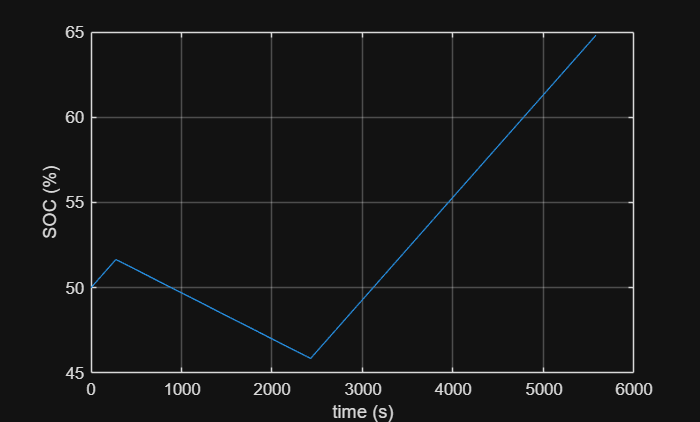

plot(t, SOC*100);
grid on;
xlabel("time (s)");
ylabel("SOC (%)");

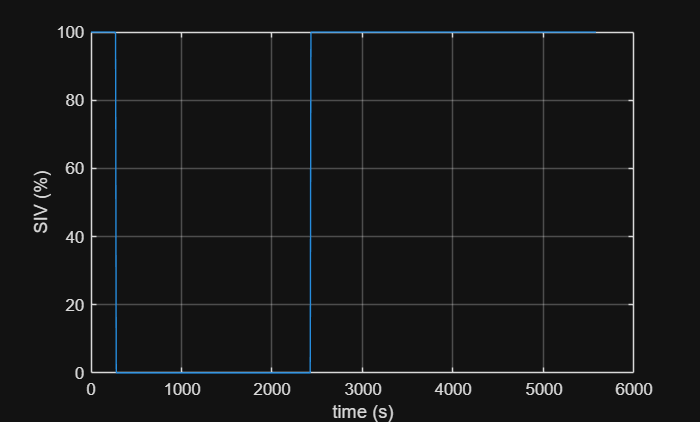


plot(t, SIV*100);
grid on;
xlabel("time (s)")
ylabel("SIV (%)")


fprintf("End time: %.1f s (%.1f orbit(s))", t(end), t(end)/(93*60));

End time: 5580.0 s (1.0 orbit(s))

## SOC change over the orbit

delta_SOC = SOC(end) - SOC(1);
delta_NRJ = delta_SOC * (2 * 4.9 * 3600) * (2 * 3.6); %here we multiply the delta_SOC by the total energy that can be stored in the batteries in A.s and then by the voltage of the batt. to obtain energy stored in J
delta_PWR = delta_NRJ / t(end); %we divide by the sim duration in seconds to obtain the power in J/s = W

fprintf("Total SoC change:\t%.1f %% (%.1f W)", delta_SOC*100, delta_PWR)

Total SoC change:	14.8 % (6.7 W)

fprintf("Maximum SOC: \t\t%.1f %%", max(SOC)*100)

Maximum SOC: 		64.8 %

fprintf("Minimum SOC: \t\t%.1f %%", min(SOC)*100)

Minimum SOC: 		45.9 %